% to move PLS toolbox down
evrimovepath('bottom')

## load data set (already exist in Matlab path)

load fisheriris.mat

% to create variables labels
iris_vlab=cellstr(['sepal lenght'; 'sepal width '; 'petal lenght'; 'petal width ']);

## Parallel coordinates plot (standardized variables)

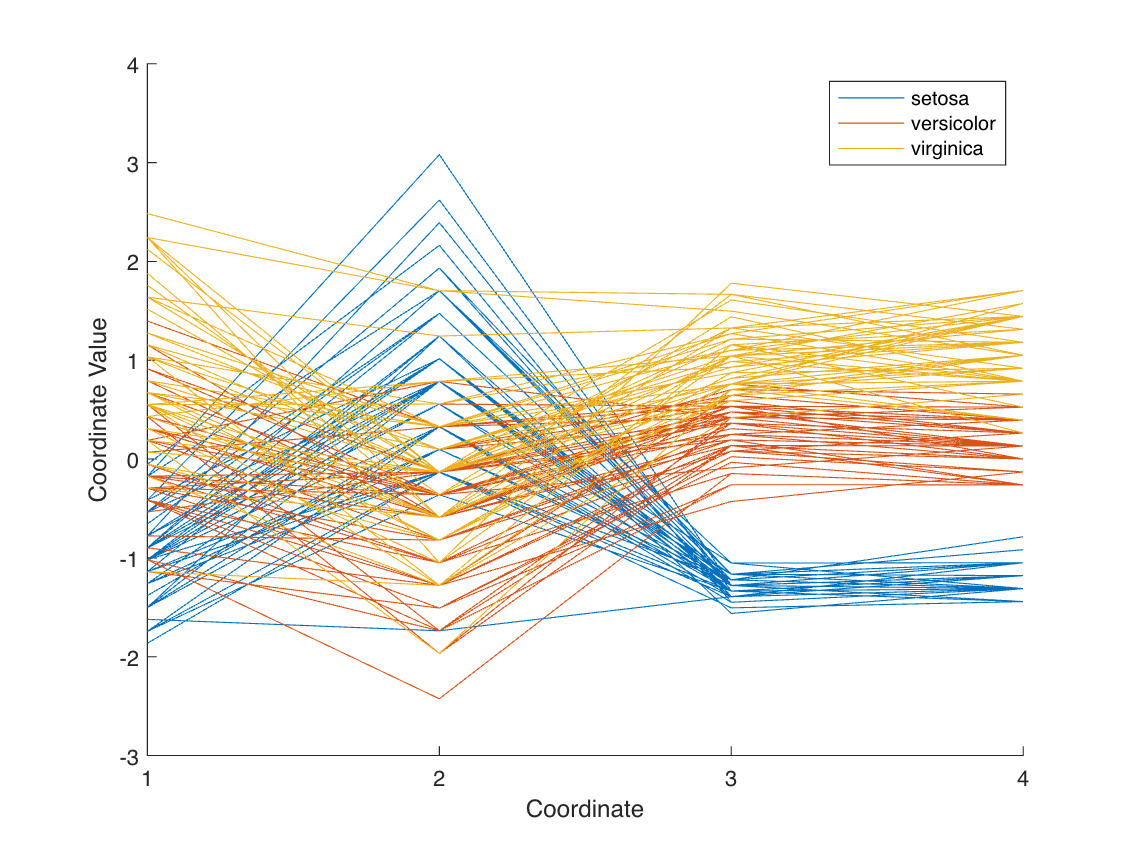

parallelcoords(meas,'group',species,'standardize','on')

## matrix plot with class index

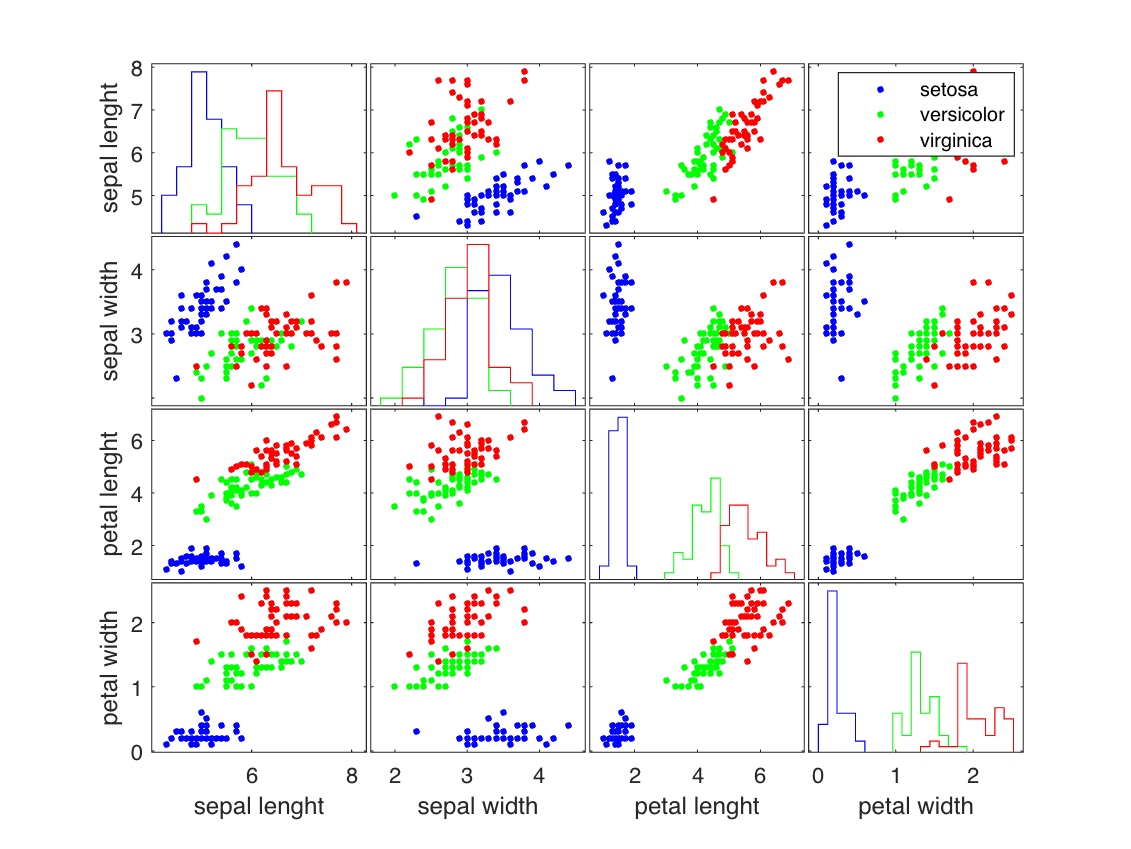

gplotmatrix(meas,[],species,[],[],[],[],'stairs',iris_vlab,iris_vlab);

## boxplot

all samples one box per variable

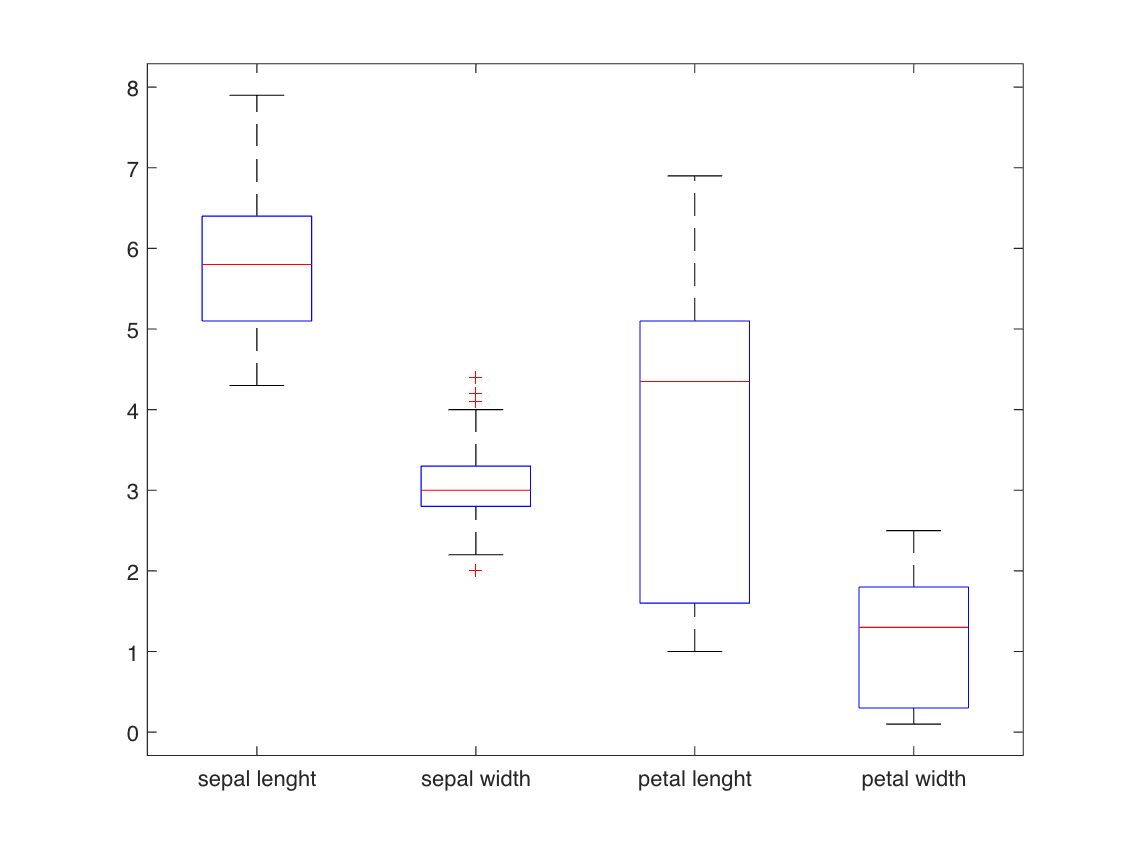

boxplot(meas,iris_vlab);

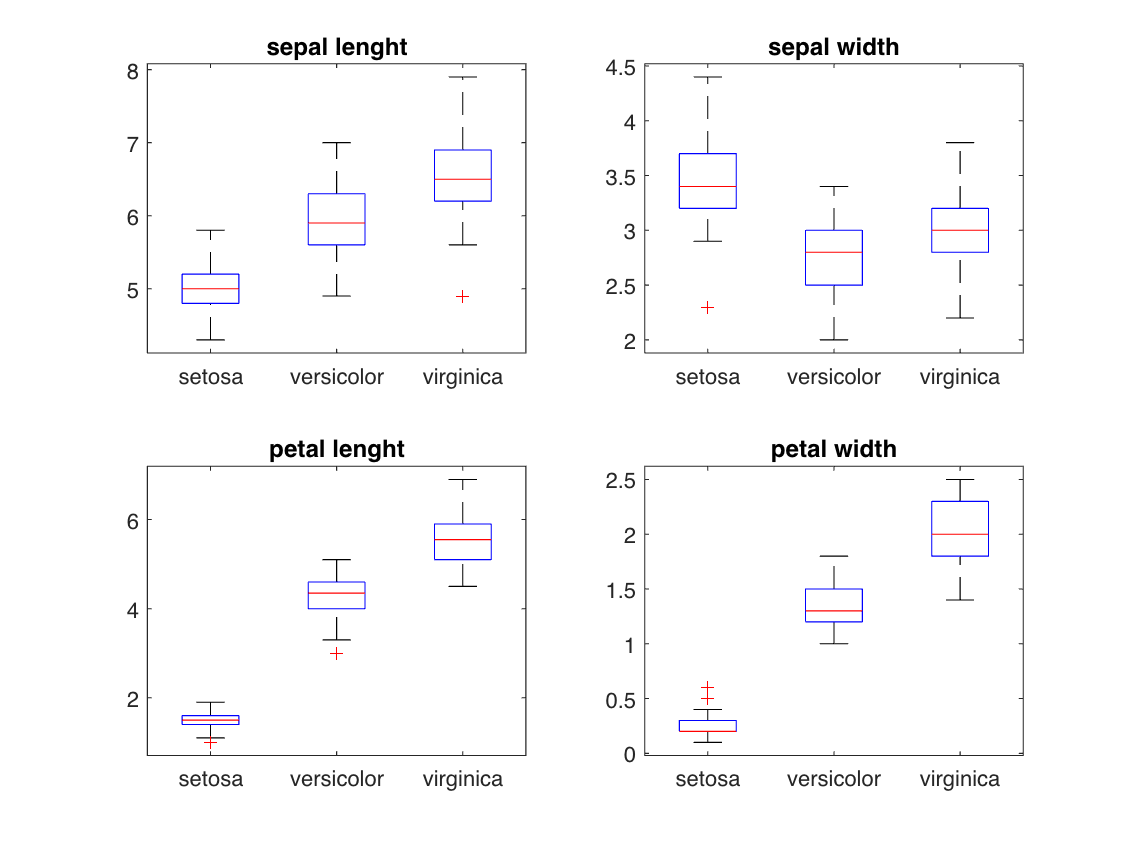

% boxplot per each variable one box per category in species
[n,m]=size(meas); 
for i=1:m
    msp=ceil(sqrt(m)); subplot(msp,msp,i);boxplot(meas(:,i),species)
    title(iris_vlab{i})
end

## scatter plot

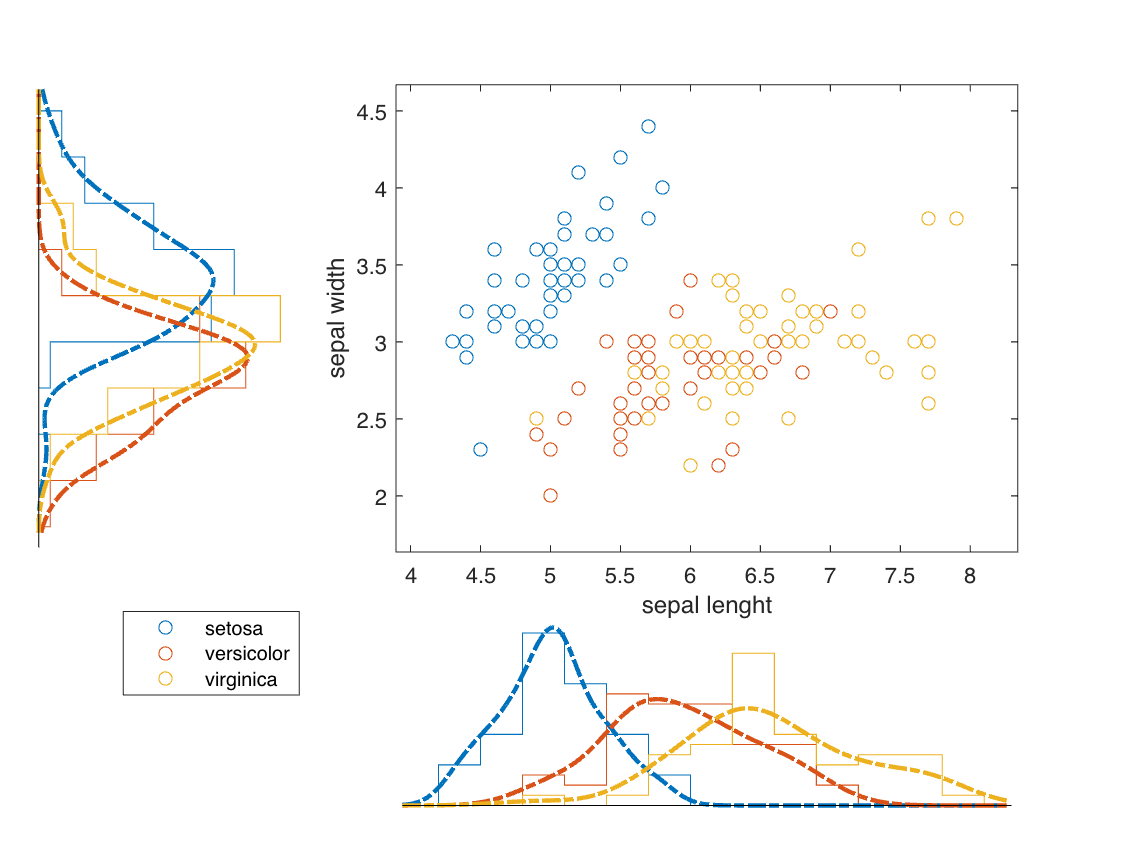

scatterhist(meas(:,1),meas(:,2),'Group',species,'Kernel','overlay'); xlabel(iris_vlab{1})
ylabel(iris_vlab{2})

## frequency histograms one per variable

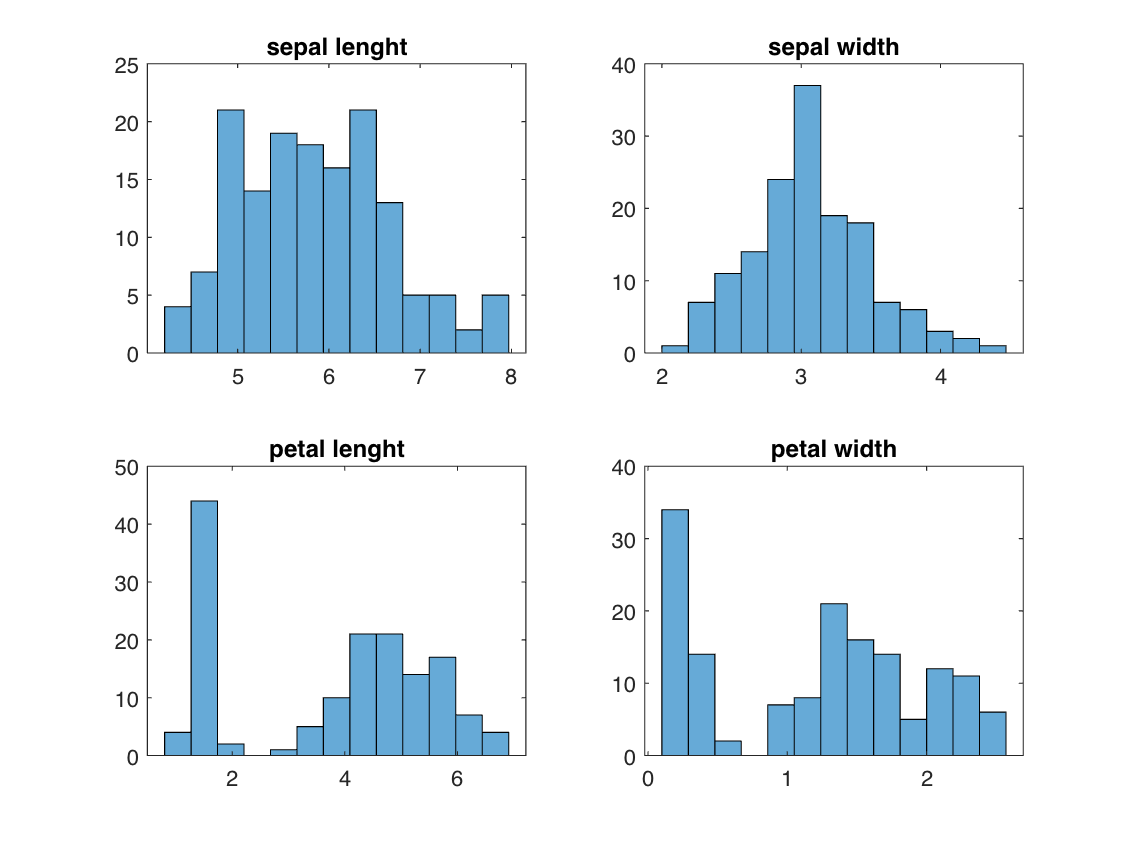

[n,m]=size(meas);
for i=1:m
    nbin=ceil(sqrt(n));
    msp=ceil(sqrt(m));
    hold on; subplot(msp,msp,i);histogram(meas(:,i),nbin);
    title(iris_vlab{i})
end

## overlappping histograms with more bins

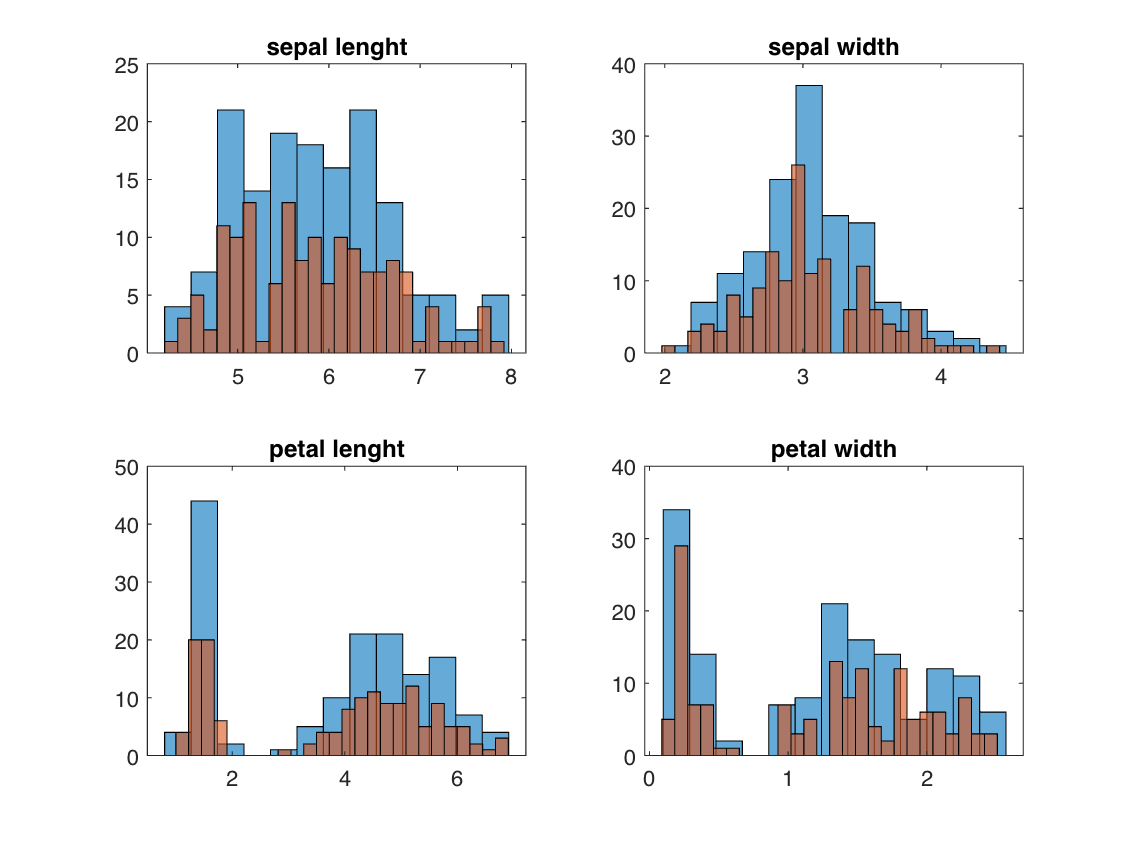

[n,m]=size(meas);
for i=1:m
    nbin=2*ceil(sqrt(n));
    msp=ceil(sqrt(m));
    hold on; subplot(msp,msp,i);histogram(meas(:,i),nbin) ;
    title(iris_vlab{i})
end

## Plotting data as an image

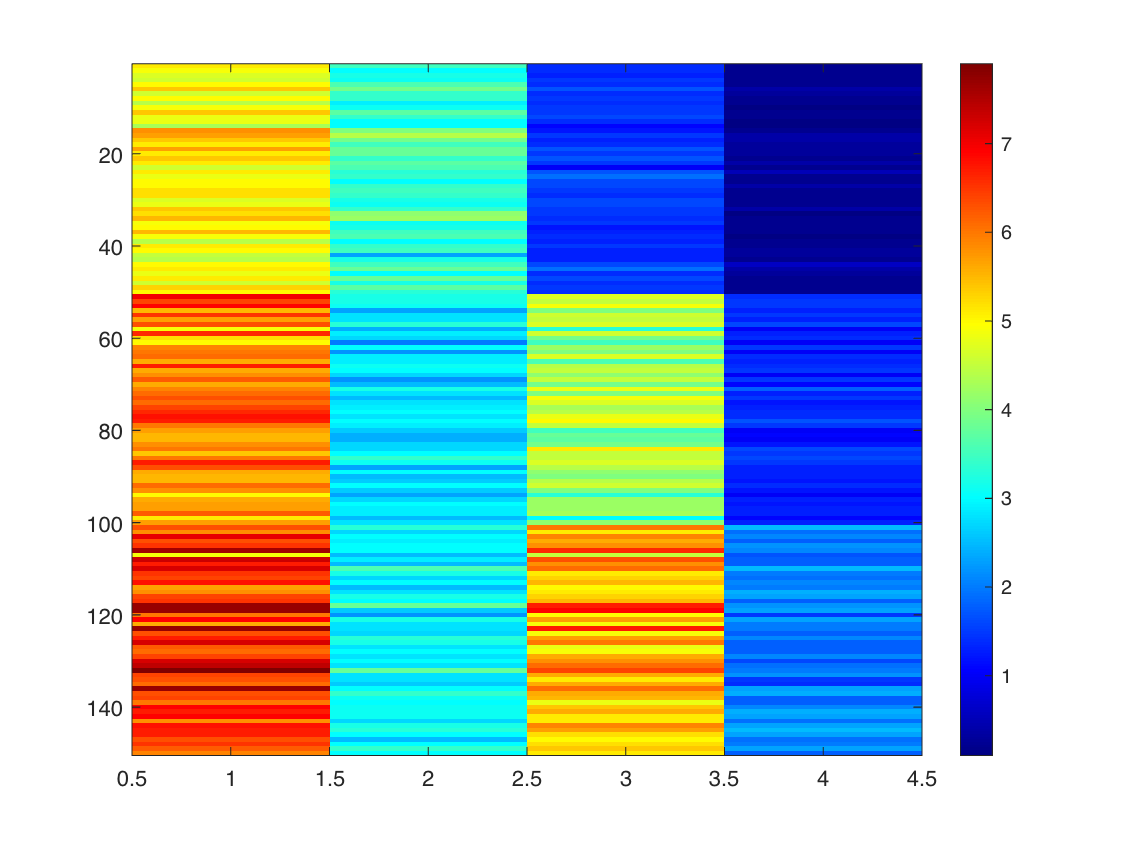

figure
imagesc(meas)
colormap('jet')
colorbar

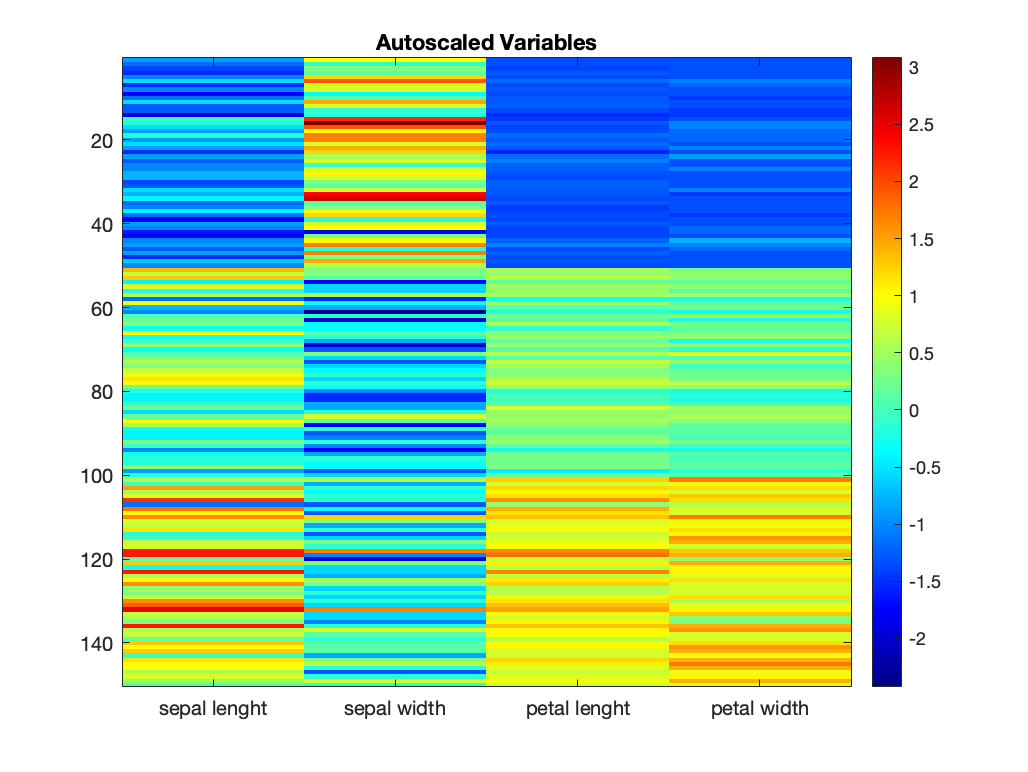


% the same but with autoscaled variables
figure
imagesc(normalize(meas, 'zscore'))
colormap('jet')
colorbar
ax=gca;
set(ax,'XTickmode','manual');
set(ax,'XTick',[1:m]) ;
set(ax,'XTicklabel',iris_vlab) ;
title('Autoscaled Variables');

## Matrice correlazione al quadrato samples by samples

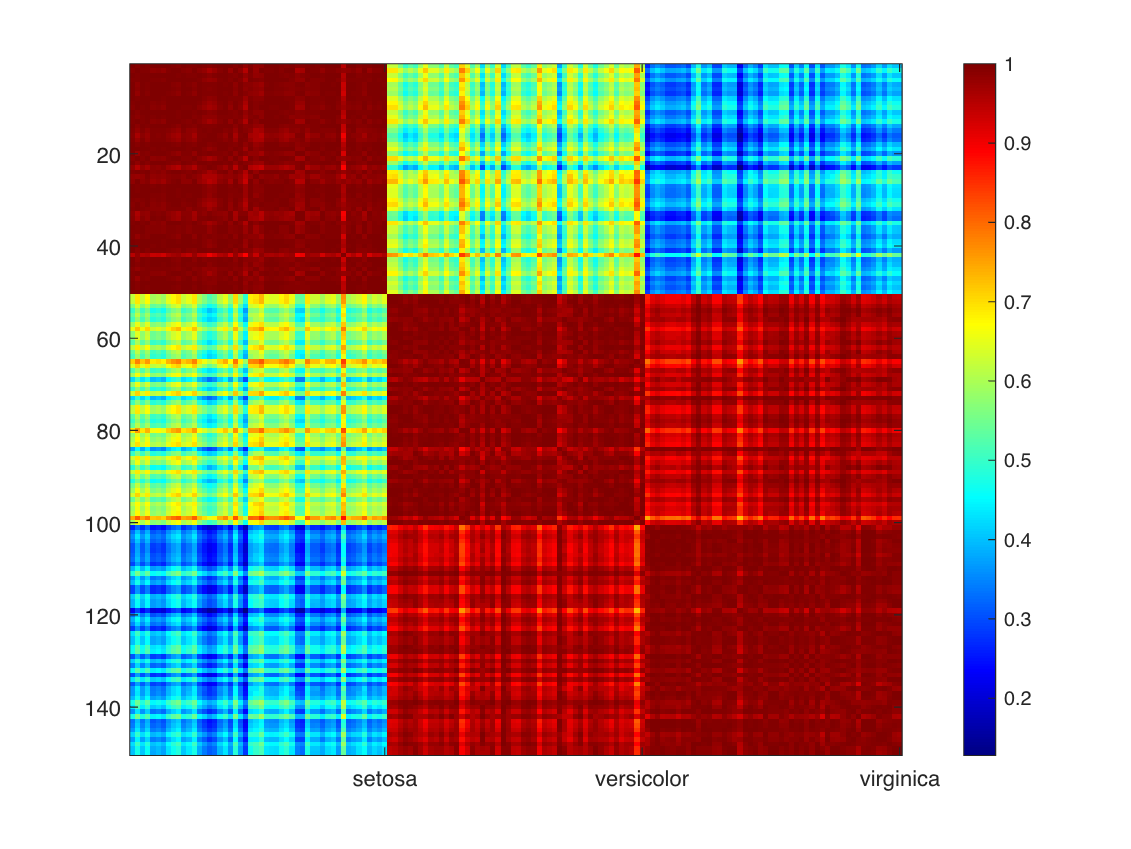

%Matrice correlazione quadrato
imagesc(corrcoef(meas').^2)
colormap('jet')
colorbar
ax=gca;
set(ax,'XTickmode','manual')
cat=unique(species,'stable');
for i=1:size(cat) 
    ic(i)=nnz(strcmp(species,cat{i}));
end
set(ax,'XTick',cumsum(ic));
set(ax,'XTickLabel',cat);